# Satellite Image Processing - YCbCr 

*Author: Avalon Royer*

*Student of Geography & Urban Planning at the Université Paris Cité.*

Satellite image processing plays an important role in land use observation and analysis as it allows for the coverage of vast areas, monitoring changes over time, and distinguishing different types of surfaces through multi-spectral data. It is particularly used for visualizing land use in hard-to-reach areas more easily, but also to support decision-making in urban planning, agriculture, and natural resource management, and to detect environmental changes such as deforestation or urbanization more quickly since it provides the ability to compare the same area at different time periods.

## Importing and Reading the Image

To read and display an image in MATLAB, use the `imshow` function after assigning the photo's title to a variable:

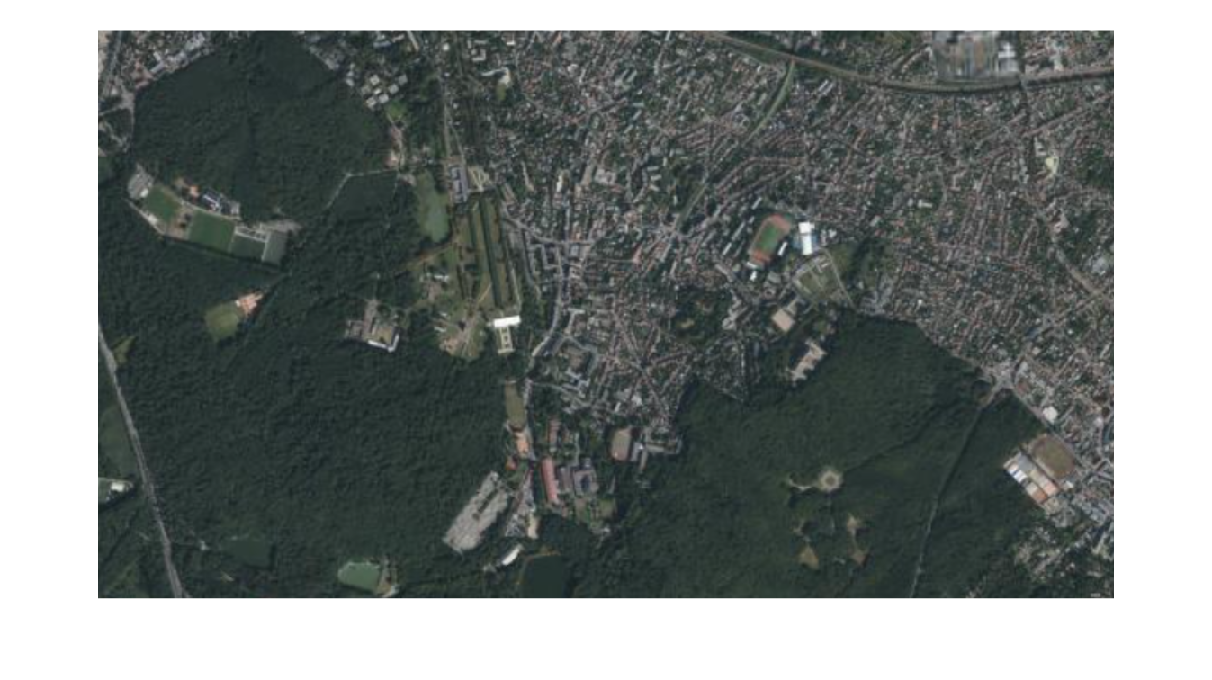

imageName="meudon_satellite.png";
RGB=imread(imageName);
imshow(imageName)

## Calling the Function

The following program uses the `createMask_satellite` function to segment a satellite image based on color criteria, creating a binary image and the RGB mask of this image:

[BW,maskedRGBImage] = createMask_satellite(RGB); %#ok<ASGLU>

## Converting RGB to HSV

Convert the image from the RGB color model to HSV:

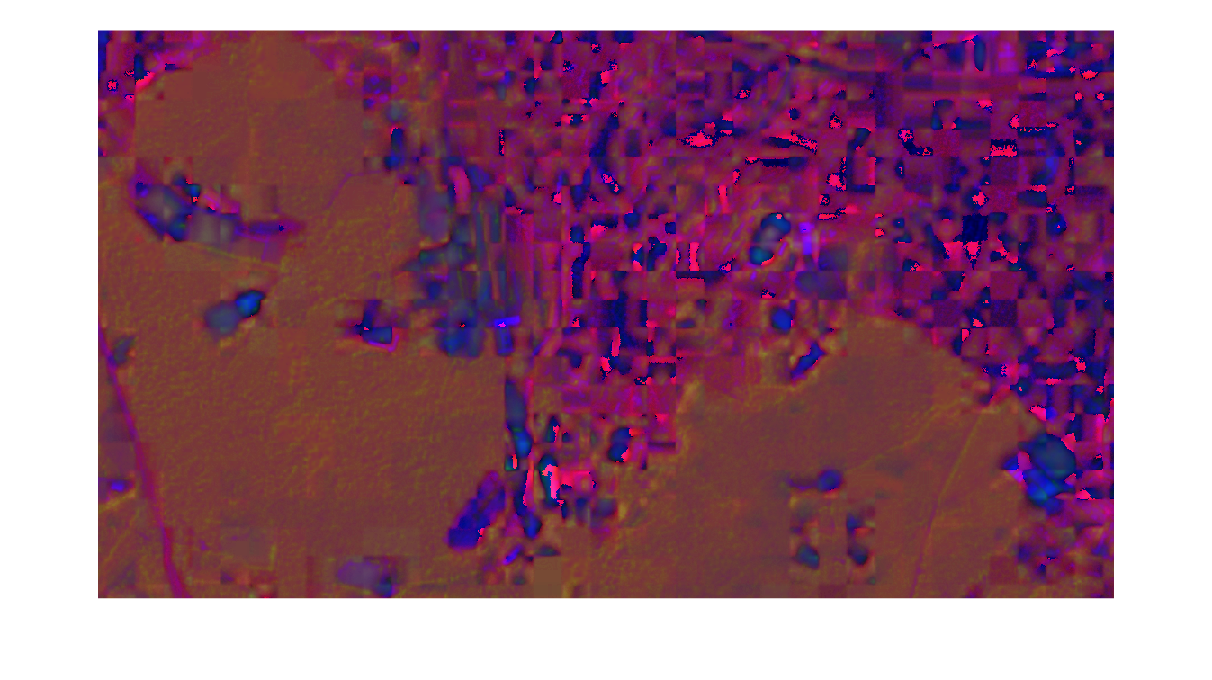

I = rgb2hsv(RGB);
imshow(I)

## Definition of Thresholds

The HSV color model consists of three components: hue, saturation, and value.

- **Hue** represents the type of color (red, green, blue, etc.) and is measured in degrees from 0° to 360° on the color wheel. Here, it has been normalized between 0 and 255.

- **Saturation** indicates the intensity of the color: the closer it gets to 0, the grayer the color will be.

- **Value** corresponds to the brightness of the color: the closer it gets to 0, the darker the color will be.

For instance, if we want to represent the portion of the territory covered by green vegetation, we will use the following maximum and minimum values:

hueMin =0.165;
hueMax =0.55;
saturationMin =0;
saturationMax =0.345;
valeurMin =0;
valeurMax =0.275;

## **Conversion to Black & White Binary Mask**

With the following commands, we will isolate and visualize the parts of the image that fall within specific color ranges by creating a binary image mask based on these thresholds. We will obtain a binary mask (`sliderBW`) in which the pixels within the specified ranges for the three color channels are set to true (1), and all other pixels are set to false (0).

Next, we will simply assign the created mask (`sliderBW`) to BW, and then display the final image using imshow.

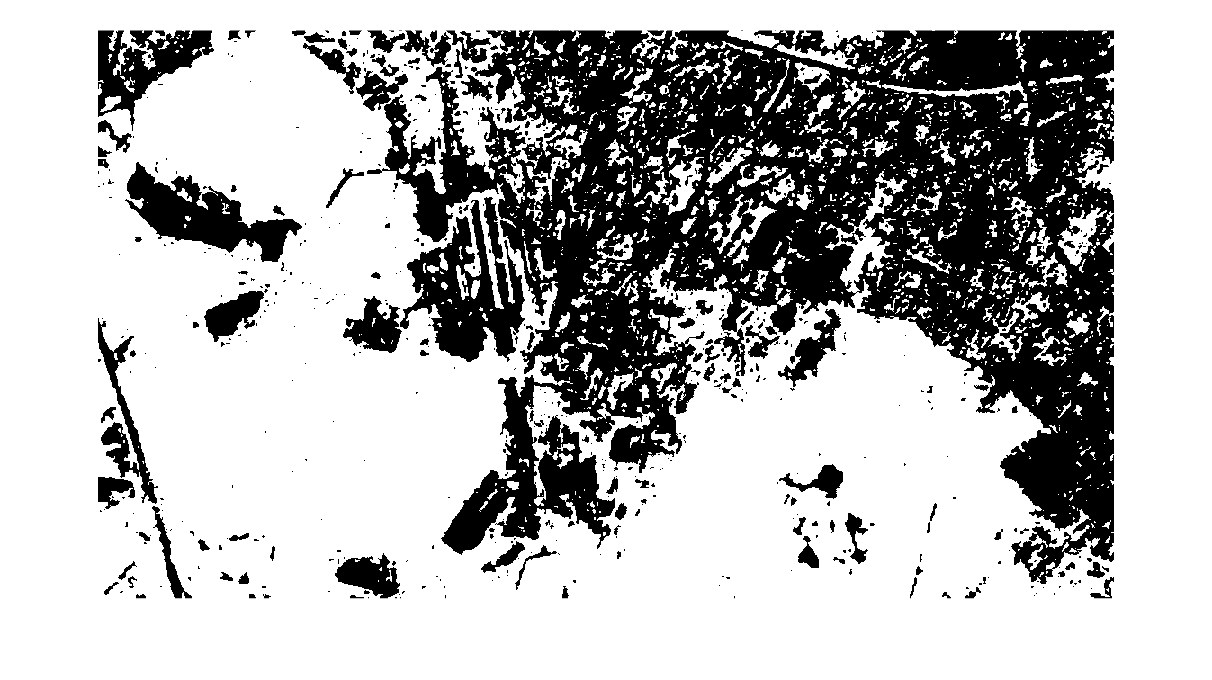

sliderBW = (I(:,:,1) >= hueMin ) & (I(:,:,1) <= hueMax) & ...
    (I(:,:,2) >= saturationMin ) & (I(:,:,2) <= saturationMax) & ...
    (I(:,:,3) >= valeurMin ) & (I(:,:,3) <= valeurMax);
BW = sliderBW;
imshow(BW)

## Final Segmentation 

We will isolate the black pixels to remove them from the image, segmenting it to leave only the part selected with the thresholds, in the RGB model.

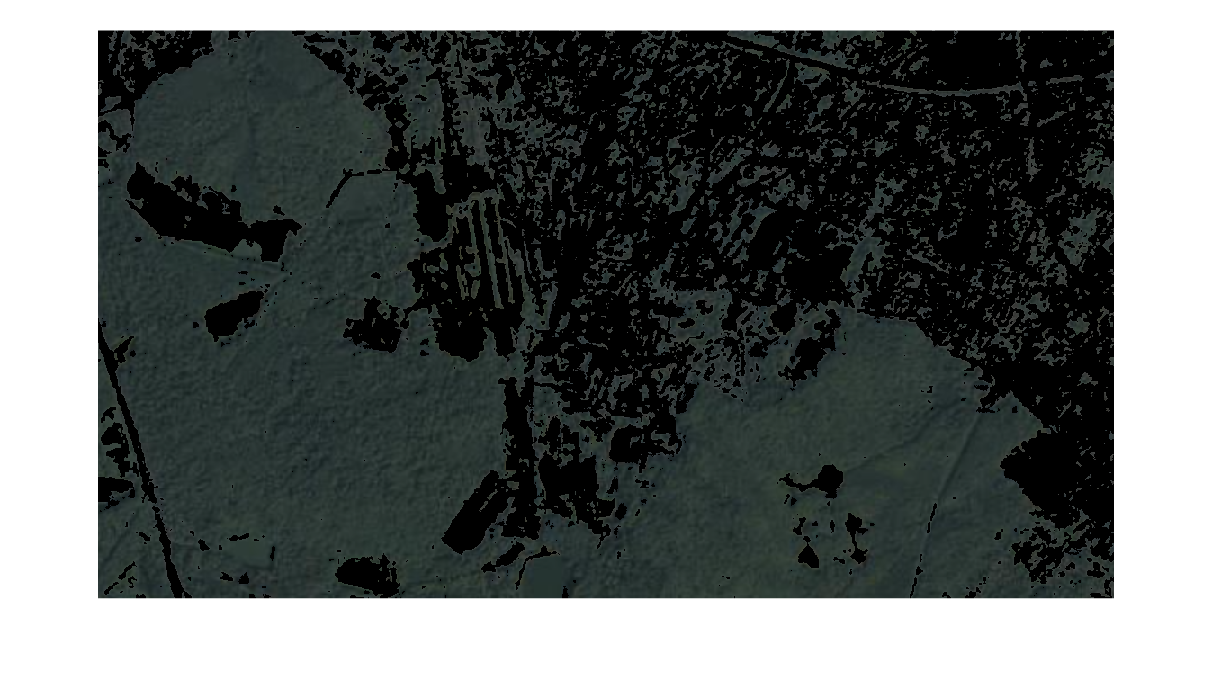

maskedRGBImage = RGB;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
imshow(maskedRGBImage)

## Calculate the Percentage of Vegetation Relative to Urbanized Areas 

Next, we want to calculate the representative percentage of the green vegetation area relative to the entire image selected for analysis. The ratio `sum(sum(BW))/(nbrow*nbcol)` gives the proportion of the image occupied by white pixels, representing the vegetation (prctVege).

[nbrow,nbcol]=size(BW);
prctVege = sum(sum(BW))/(nbrow*nbcol)

prctVege = 0.5900

*Image: Google Maps*